## Parse the data from the specs

clear
structure = SpecParser("global_specs.txt")

structure = struct with fields:
               task_type: 'wav'
            wav_filename: 'animal_call.wav'
                  wav_fs: 20000
             signal_type: 'tone'
                      fs: 10000
       signal_duration_s: 3
           periodicity_s: 0.5000
             frequencies: [1000 2000 4000 8000]
     spectral_resolution: 0.5000
             window_type: 'hann'
            stft_overlap: 50
               filtering: 'iir'
            filter_order: 2
    approximation_method: 'butterworth'
             filter_type: 'lp'
       cut_off_frequency: 1000
              x_lim_time: 2
         y_lim_amplitude: 1
             x_axis_type: 'log'
             y_axis_type: 'log'
         x_lim_frequency: 'nyquist'
                y_lim_au: 40


## Specify save location

destdirectory = "Results";
mkdir(destdirectory);

## Signal selection, .wav read, resample

task_type = structure.task_type % Determine whether to generate or read .wav

task_type = 'wav'

if strcmp(task_type, 'wav') % Check if the task is related to audio processing

    % Get the directory and file name for the audio file
    dir_name = pwd; % Current working directory
    f_name = structure.wav_filename; % Audio file name from structure

    % Read the audio file
    [y, fs_o] = audioread(fullfile(dir_name, f_name)); % Load audio and original sampling frequency
    y = y(:, 1); % Convert stereo to mono by selecting one channel
    
    % Target sampling frequency
    fs = structure.wav_fs; % Desired sampling frequency from structure
    
    % Resample the audio if the sampling frequency is different
    if fs_o ~= fs
        signal = resample(y, fs, fs_o); % Resample from original to target frequency
    else
        signal = y; % No resampling needed
    end
    
    % Generate time vectors for both signals
    t_original = (0:length(y) - 1) / fs_o; % Time vector for original signal
    t_resampled = (0:length(signal) - 1) / fs; % Time vector for resampled signal
    
    % Save the processed data (time and signal) to files (optional)
    %save_data({t_resampled, signal}, {'Time', 'Amplitude'}, 'Results/audio_signal_resampled');
    %save_data({t_original, y}, {'Time', 'Amplitude'}, 'Results/audio_signal_original');

end


## Generate signal

if strcmp(task_type, 'generate') % Check if the task is to generate a signal

    % Extract parameters from the structure
    type = structure.signal_type; % Signal type ('rect', 'tone', 'tone-complex', 'noise')
    fs = structure.fs; % Sampling frequency
    duration = structure.signal_duration_s; % Duration of the signal in seconds
    frequencies = structure.frequencies; % Frequencies to include in the signal
    t = 0:1/fs:duration-1/fs; % Time vector for the signal
    signal = zeros(1, length(t)); % Initialize the signal array with zeros

    % Generate a rectangular wave if specified
    if strcmp(type, 'rect')
        periodicity = structure.periodicity_s; % Periodicity of the rectangular wave
        % Use the sine function and the sign function to generate a rectangular waveform
        signal = sign(sin(2 * pi / periodicity * t)); % Construct the rectangular wave
    end

    % Generate a tone (sum of sinusoidal components) if specified
    if strcmp(type, 'tone')
        for i = 1:length(frequencies) % Iterate through the list of frequencies
            signal = signal + cos(2 * pi * frequencies(i) * t); % Add sinusoidal component
        end
    end

    % Generate a tone-complex (sum of sinusoidal components with random phases) if specified
    if strcmp(type, 'tone-complex')
        for i = 1:length(frequencies) % Iterate through the list of frequencies
            phase = rand() * 2 * pi; % Random phase between 0 and 2π
            signal = signal + cos(2 * pi * frequencies(i) * t + phase); % Add sinusoidal component with random phase
        end
    end

    % Generate random noise if specified
    if strcmp(type, 'noise')
        signal = rand(1, fs * duration) - 0.5; % Generate random values in the range [-0.5, 0.5]
    end

    % Save the generated signal to a file
    % 'save_data' should save time and amplitude vectors with appropriate labels
    save_data({t, signal}, {'Time', 'Amplitude'}, 'Results/generated_signal');

end

## DFT.1

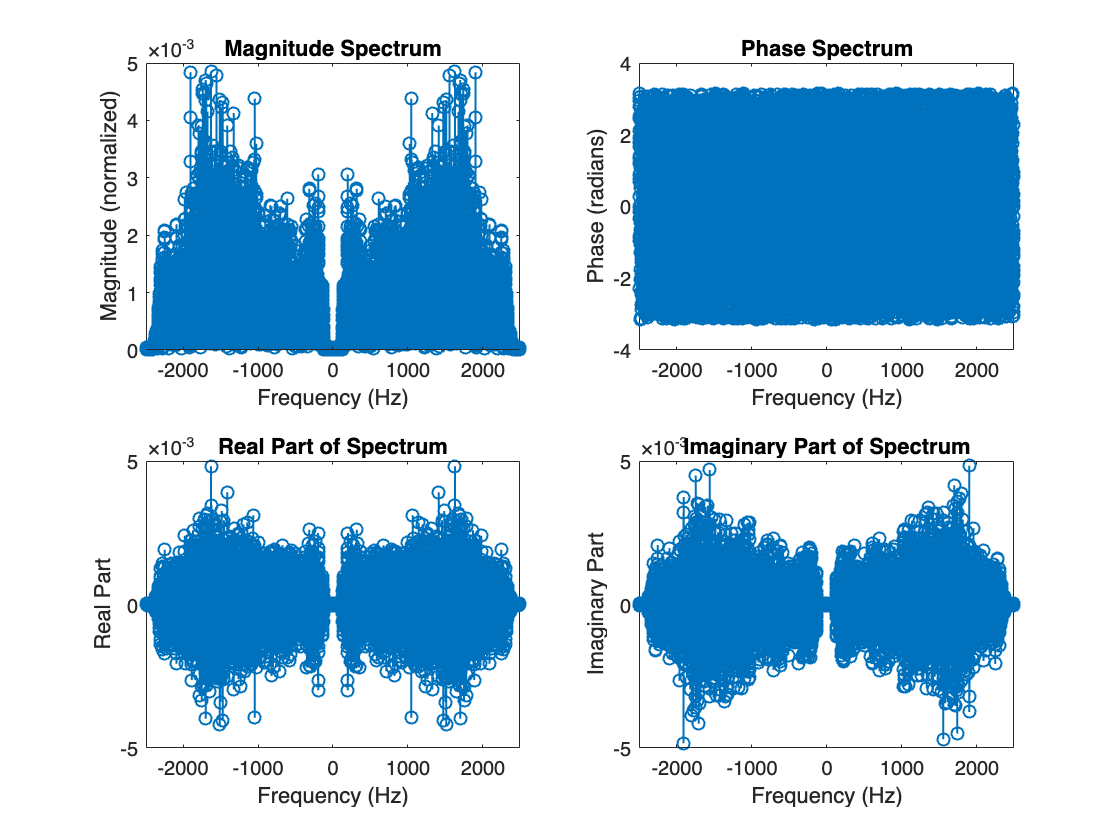

%% DFT of Both Signals

% Spectral resolution from structure
spectral_resolution = structure.spectral_resolution; % Required spectral resolution

% Compute DFT of Original Signal
[Y_original, f_original] = make_spectrum(y, fs_o, spectral_resolution);

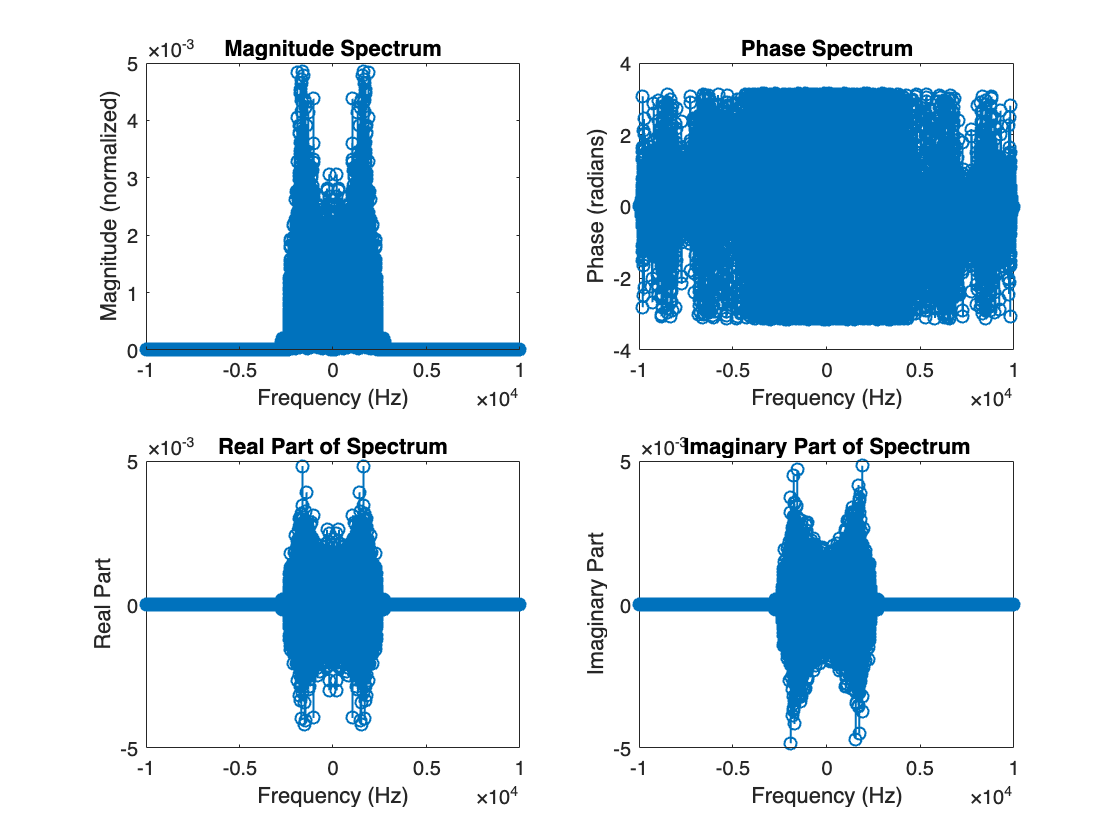


% Compute DFT of Resampled Signal
[Y_resampled, f_resampled] = make_spectrum(signal, fs, spectral_resolution);

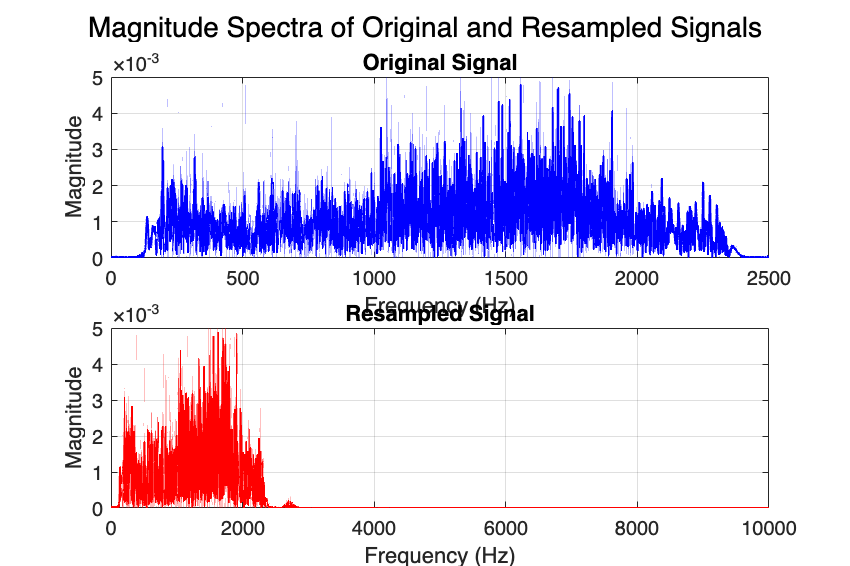

Figure saved as Results/Magnitude_Spectra_Original_and_Resampled.pdf




% Plot the Magnitude Spectra of Both Signals

figure;
sgtitle('Magnitude Spectra of Original and Resampled Signals', 'FontSize', 14);

% Original Signal Spectrum
subplot(2, 1, 1);
plot(f_original, abs(Y_original), 'b', 'LineWidth', 1);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Original Signal');
xlim([0 fs_o/2]);
grid on;

% Resampled Signal Spectrum
subplot(2, 1, 2);
plot(f_resampled, abs(Y_resampled), 'r', 'LineWidth', 1);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Resampled Signal');
xlim([0 fs/2]);
grid on;

% Optional: Save the plot
save_plot('Results/Magnitude_Spectra_Original_and_Resampled', 'pdf');

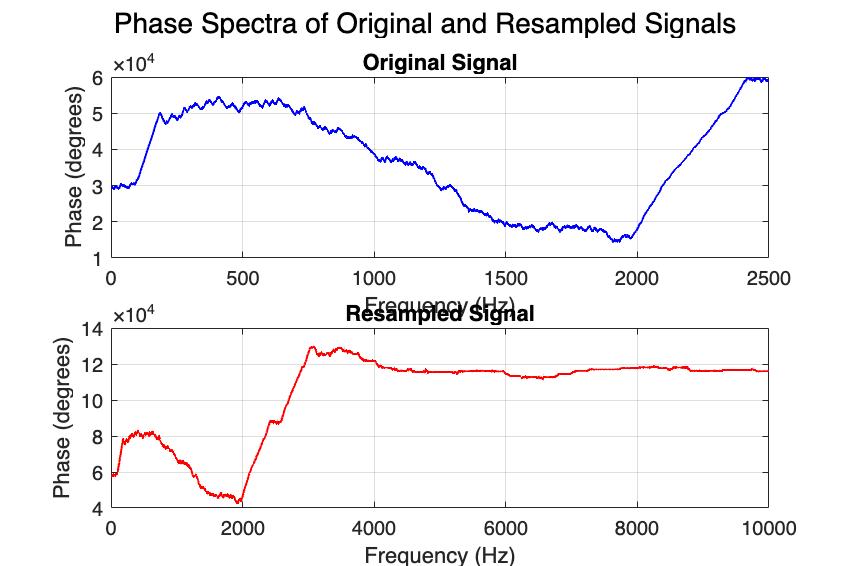

Figure saved as Results/Phase_Spectra_Original_and_Resampled.pdf




% Plot the Phase Spectra of Both Signals

figure;
sgtitle('Phase Spectra of Original and Resampled Signals', 'FontSize', 14);

% Original Signal Spectrum
subplot(2, 1, 1);
plot(f_original, unwrap(angle(Y_original)) * 180 / pi, 'b', 'LineWidth', 1);
xlabel('Frequency (Hz)');
ylabel('Phase (degrees)');
title('Original Signal');
xlim([0 fs_o/2]);
grid on;

% Resampled Signal Spectrum
subplot(2, 1, 2);
plot(f_resampled, unwrap(angle(Y_resampled)) * 180 / pi, 'r', 'LineWidth', 1);
xlabel('Frequency (Hz)');
ylabel('Phase (degrees)');
title('Resampled Signal');
xlim([0 fs/2]);
grid on;

% Optional: Save the plot
save_plot('Results/Phase_Spectra_Original_and_Resampled', 'pdf');

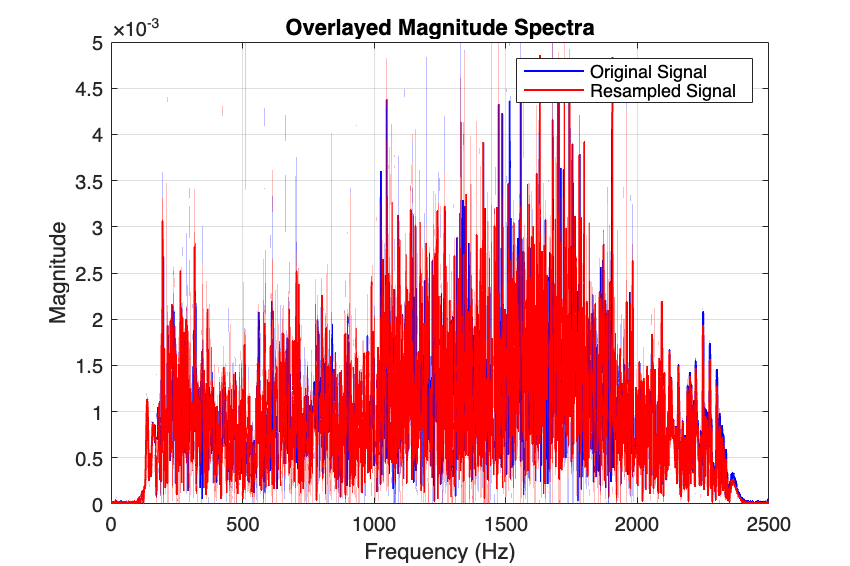

Figure saved as Results/Overlayed_Magnitude_Spectra.pdf



% Overlayed Magnitude Spectra

figure;
plot(f_original, abs(Y_original), 'b', 'LineWidth', 1);
hold on;
plot(f_resampled, abs(Y_resampled), 'r', 'LineWidth', 1);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Overlayed Magnitude Spectra');
legend('Original Signal', 'Resampled Signal');
xlim([0 min(fs_o/2, fs/2)]);
grid on;
hold off;

% Optional: Save the plot
save_plot('Results/Overlayed_Magnitude_Spectra', 'pdf');

## DFT

% Generate the normalized spectrum of a signal.
% Inputs:
%   signal - The input signal in the time domain.
%   fs - Sampling frequency of the signal.
%   spectral_resolution - Desired spectral resolution (e.g., [0.2, 0.5, 1]).
%
% The function calculates the normalized spectrum using the Discrete Fourier Transform (DFT).
% The spectral resolution is achieved by resampling the transformed signal to match the required resolution.
% Note: The `resample` function requires integers for its inputs `p` and `q`,
% which means the inverse of the spectral resolution (1/spectral_resolution) must be an integer.

spectral_resolution = structure.spectral_resolution; % Required spectral resolution

% Call the spectrum generation function to calculate the spectrum (Y) and frequency vector (f)
[Y, f] = make_spectrum(signal, fs, spectral_resolution); % Function to compute the DFT and normalize

% Save spectrum and frequency vector
%save_data({f, abs(Y), real(Y), imag(Y)},{'Frequency', 'Magnitude', 'Real', 'Imaginary'},'dft_signal');

## STFT.1

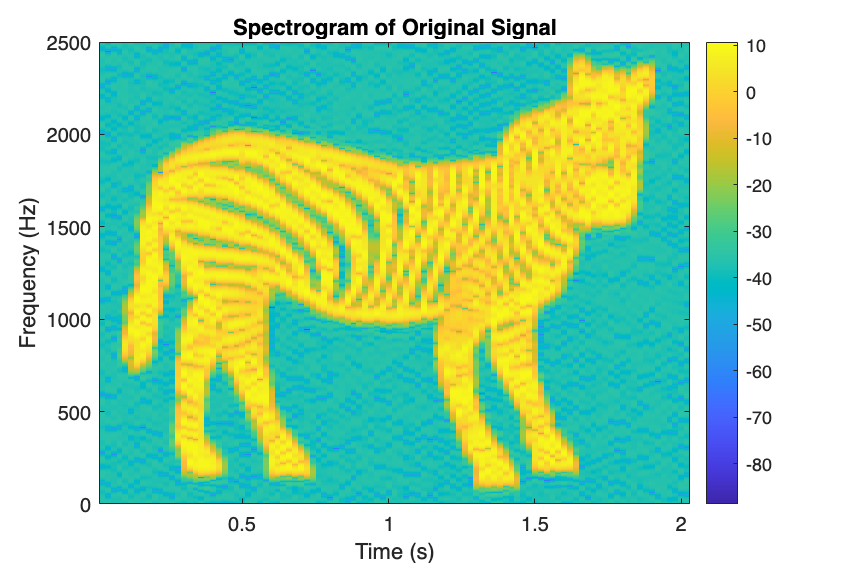

Figure saved as Results/STFT_Original.pdf


%% STFT of Both Signals

% Common parameters from structure
spectral_resolution = structure.spectral_resolution; % Frequency resolution
window_type = structure.window_type; % Window type ('hann', 'hamming', 'rect')
overlap = structure.stft_overlap; % Overlap percentage for STFT

% ---------- STFT of Original Signal ----------

% Sampling frequency and signal
fs_original = fs_o;
signal_original = y;

% DFT length for desired spectral resolution
N_original = round(fs_original / spectral_resolution);

% Calculate window length
winLength_original = 200; % Adjust as needed round(N_original / 15)

% Select window type
switch window_type
    case "hann"
        winSTFT_original = hann(winLength_original, 'periodic');
    case "hamming"
        winSTFT_original = hamming(winLength_original, 'periodic');
    case "rect"
        winSTFT_original = ones(winLength_original, 1);
    otherwise
        error("Invalid window type. Use 'hann', 'hamming', or 'rect'.");
end

% Overlap samples
overlap_samples_original = round(winLength_original * overlap / 100);

% Compute STFT
[y_stft_original, f_stft_original, t_stft_original] = stft(signal_original, fs_original, ...
    'Window', winSTFT_original, ...
    'OverlapLength', overlap_samples_original, ...
    'FFTLength', N_original, ...
    'FrequencyRange', 'onesided');

% ---------- STFT of Resampled Signal ----------

% Sampling frequency and signal
fs_resampled = fs;
signal_resampled = signal;

% DFT length for desired spectral resolution
N_resampled = round(fs_resampled / spectral_resolution);

% Calculate window length
winLength_resampled = round(N_resampled / 250); % Adjust as needed

% Select window type
switch window_type
    case "hann"
        winSTFT_resampled = hann(winLength_resampled, 'periodic');
    case "hamming"
        winSTFT_resampled = hamming(winLength_resampled, 'periodic');
    case "rect"
        winSTFT_resampled = ones(winLength_resampled, 1);
    otherwise
        error("Invalid window type. Use 'hann', 'hamming', or 'rect'.");
end

% Overlap samples
overlap_samples_resampled = round(winLength_resampled * overlap / 100);

% Compute STFT
[y_stft_resampled, f_stft_resampled, t_stft_resampled] = stft(signal_resampled, fs_resampled, ...
    'Window', winSTFT_resampled, ...
    'OverlapLength', overlap_samples_resampled, ...
    'FFTLength', N_resampled, ...
    'FrequencyRange', 'onesided');

% Plot the Spectrogram of the Original Signal
figure;
imagesc(t_stft_original, f_stft_original, 20 * log10(abs(y_stft_original)));
axis xy; % Correct the axis orientation
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram of Original Signal');
colorbar;
%colormap jet; % Apply the jet colormap

% Optional: Save the spectrogram plot of the original signal
save_plot('Results/STFT_Original', 'pdf');

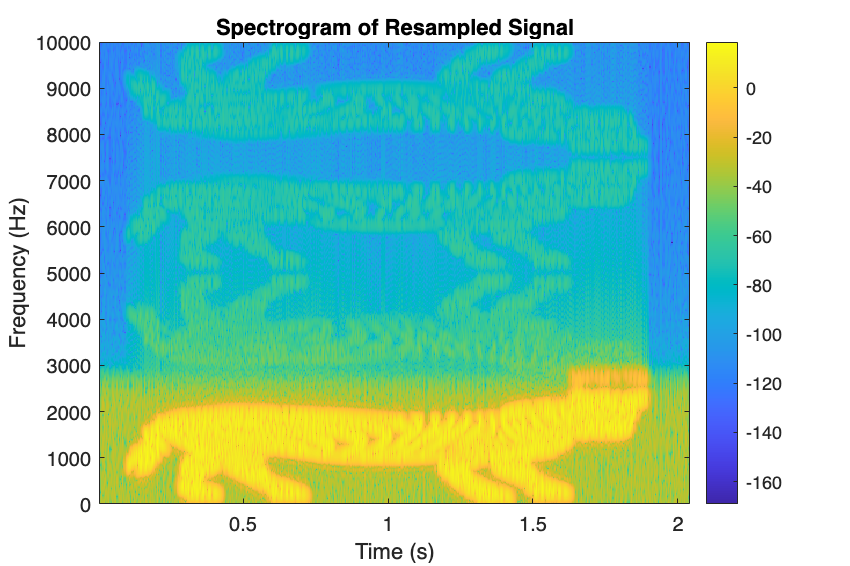

Figure saved as Results/STFT_Resampled.pdf



% Plot the Spectrogram of the Resampled Signal
figure;
imagesc(t_stft_resampled, f_stft_resampled, 20 * log10(abs(y_stft_resampled)));
axis xy;
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram of Resampled Signal');
colorbar;
%colormap jet; % Apply the jet colormap

% Optional: Save the spectrogram plot of the resampled signal
save_plot('Results/STFT_Resampled', 'pdf');

## STFT

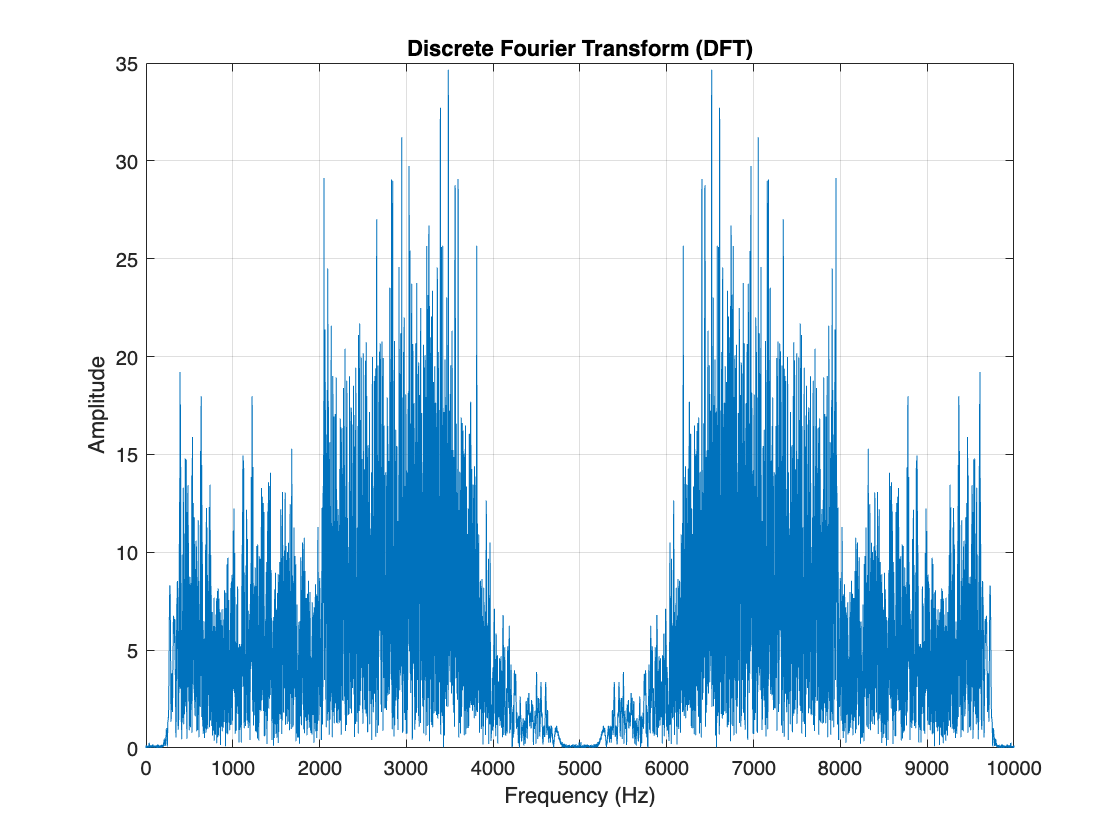

% Inputs and structure parameters
signal = y; % Input signal
%y = signal;
fs = structure.fs; % Sampling frequency
spectral_resolution = structure.spectral_resolution; % Frequency resolution
window_type = structure.window_type; % Window type ('hann', 'hamming', 'rect')
overlap = structure.stft_overlap; % Overlap percentage for STFT

% Validate window type
if ~ismember(window_type, ["hann", "hamming", "rect"])
    error("Invalid window type. Use 'hann', 'hamming', or 'rect'.");
end

% DFT length for desired spectral resolution
N = round(fs / spectral_resolution);
L = length(signal);

% Window signal for DFT based on the signal length and DFT length
if N < L
    % Use the appropriate window type
    switch window_type
        case "hann"
            winDFT = hann(N);
        case "hamming"
            winDFT = hamming(N);
        case "rect"
            winDFT = ones(N, 1);
    end
    y_win = winDFT .* signal(1:N); % Window only the first N samples
else
    switch window_type
        case "hann"
            winDFT = hann(L);
        case "hamming"
            winDFT = hamming(L);
        case "rect"
            winDFT = ones(L, 1);
    end
    y_win = winDFT .* signal; % Window the entire signal
end

% Compute the DFT
y_dft = fft(y_win, N);

% Plot the DFT
figure;
freq_dft = (0:N-1) * (fs / N); % Frequency axis for DFT
plot(freq_dft, abs(y_dft));
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('Discrete Fourier Transform (DFT)');
grid on;

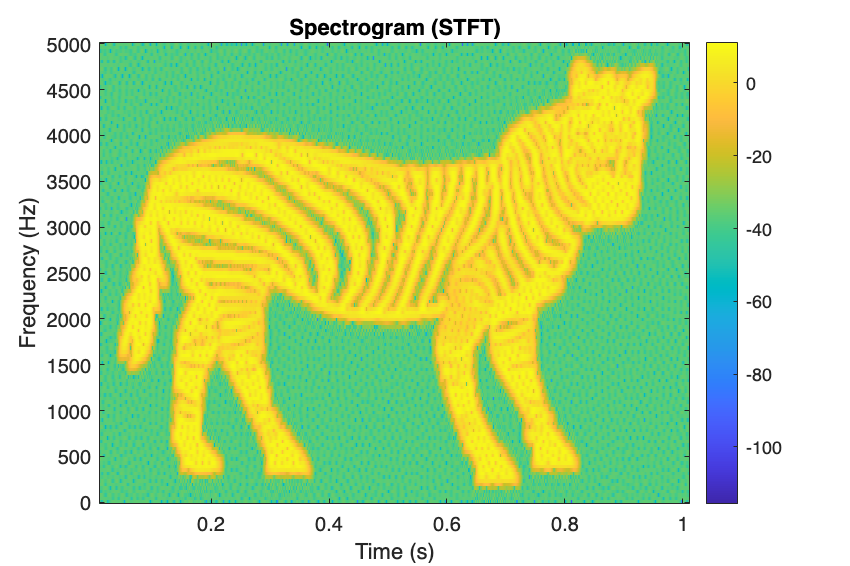

Figure saved as Results/STFT_Original.pdf



% Calculate window length for STFT
winLength = 200; % Arbitrary choice for time-frequency resolution balance round(N / 15)
switch window_type
    case "hann"
        winSTFT = hann(winLength);
    case "hamming"
        winSTFT = hamming(winLength);
    case "rect"
        winSTFT = ones(winLength, 1);
    otherwise
        error("Invalid window type. Use 'hann', 'hamming', or 'rect'.");
end

% Compute STFT
overlap_samples = round(winLength * overlap / 51);
[y_stft, f_stft, t_stft] = stft(signal, fs, ...
    'FrequencyRange', 'onesided', ...
    'Window', winSTFT, ...
    'OverlapLength', overlap_samples, ...
    'FFTLength', 2^(nextpow2(winLength))); % Ensure FFT length is a power of 2

% Plot the STFT (Spectrogram)
figure;
imagesc(t_stft, f_stft, 20 * log10(abs(y_stft))); % Convert to dB scale
axis xy;
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram (STFT)');
colorbar;

% Optional: Save the spectrogram plot
save_plot('Results/STFT_Original', 'pdf');

%saveas(gcf, 'STFT.pdf');

## Filter design

% Ensure 'fs' (sampling frequency) is defined based on task_type
if strcmp(task_type, 'wav')
    fs = structure.wav_fs;
else
    fs = structure.fs;
end

% Extract filter specifications from the structure
filtering = structure.filtering;        % 'iir' or 'fir'
filter_type = structure.filter_type;    % 'lp', 'hp', 'bp', 'bs'
approximation_method = structure.approximation_method; % e.g., 'butterworth'
filter_order = structure.filter_order;  % e.g., 2
cutoff_freq = structure.cut_off_frequency; % e.g., 10000 Hz

% Normalize the cutoff frequency
cutoff_freqs_norm = cutoff_freq / (fs / 2);

% Validate cutoff frequencies based on filter type
if strcmpi(filter_type, 'lp') || strcmpi(filter_type, 'hp')
    if numel(cutoff_freq) ~= 1
        error('Lowpass and highpass filters require a single cutoff frequency.');
    end
elseif strcmpi(filter_type, 'bp') || strcmpi(filter_type, 'bs')
    if numel(cutoff_freq) ~= 2
        error('Bandpass and bandstop filters require two cutoff frequencies.');
    end
else
    error('Invalid filter type specified.');
end

% Handle cutoff frequency at Nyquist frequency for IIR filters
if strcmpi(filtering, 'iir') && any(cutoff_freqs_norm >= 1)
    % Adjust the cutoff frequency slightly less than fs/2
    epsilon = 1e-6; % Small number to adjust the cutoff frequency
    cutoff_freq(cutoff_freq >= fs / 2) = fs / 2 - epsilon;
    cutoff_freqs_norm = cutoff_freq / (fs / 2);
    warning('Cutoff frequency for IIR filter adjusted to be less than fs/2.');
end

% Validate normalized cutoff frequencies
if any(cutoff_freqs_norm <= 0) || any(cutoff_freqs_norm >= 1)
    error('Normalized cutoff frequencies must be between 0 and 1 (non-inclusive).');
end

% Design the filter based on the specified type
if strcmpi(filtering, 'iir')
    % Design an IIR filter
    [b_iir, a_iir] = designIIRfilter(filter_type, approximation_method, filter_order, cutoff_freqs_norm);
    b = b_iir;
    a = a_iir;

elseif strcmpi(filtering, 'fir')
    % Design an FIR filter
    % Map filter types to fir1 options
    switch lower(filter_type)
        case 'lp'
            b_fir = fir1(filter_order, cutoff_freqs_norm, 'low');
        case 'hp'
            b_fir = fir1(filter_order, cutoff_freqs_norm, 'high');
        case 'bp'
            b_fir = fir1(filter_order, cutoff_freqs_norm, 'bandpass');
        case 'bs'
            b_fir = fir1(filter_order, cutoff_freqs_norm, 'stop');
        otherwise
            error('Invalid filter type specified.');
    end
    a_fir = 1; % FIR filters have a denominator of 1
    b = b_fir;
    a = a_fir;

else
    error('Invalid filtering type specified. Choose ''iir'' or ''fir''.');
end

% Apply the designed filter to the signal
filtered_data_signal = filter(b, a, signal);

% Generate time vector for the filtered signal
t_filtered = (0:length(filtered_data_signal) - 1) / fs;
t_filtered = t_filtered(:);


%% Display and Save Filter Coefficients

% Ensure 'a' and 'b' are column vectors
if isrow(a)
    a = a';
end
if isrow(b)
    b = b';
end

% Convert 'a' and 'b' to row vectors for display
a_row = a(:).';
b_row = b(:).';

% Convert coefficients to string representations
a_str = num2str(a_row);
b_str = num2str(b_row);

% Display the filter coefficients
disp('Filter Coefficients:');

Filter Coefficients:


disp(['b (Numerator): ', b_str]);

b (Numerator): 0.020083    0.040167    0.020083


disp(['a (Denominator): ', a_str]);

a (Denominator): 1      -1.561     0.64135



% Save the filter coefficients to a text file
save_coefficients(a, b);

%% Save Filtered Signal (Optional)

% Save the filtered signal data (assuming 'save_data' function exists)
% save_data({t_filtered, filtered_data_signal}, {'Time', 'Filtered Amplitude'}, 'filtered_signal');

disp('Filtering completed successfully.');

Filtering completed successfully.


## Plotting

Read parameters from spec sheet

% Time plots
x_lim = structure.x_lim_time;
y_lim = structure.y_lim_amplitude;

% Frequency plots
x_axis_type = structure.x_axis_type;
y_axis_type = structure.y_axis_type;
x_lim_freq = structure.x_lim_frequency; 
y_lim_au = structure.y_lim_au;

**1) Time signals: Original + Filtered**

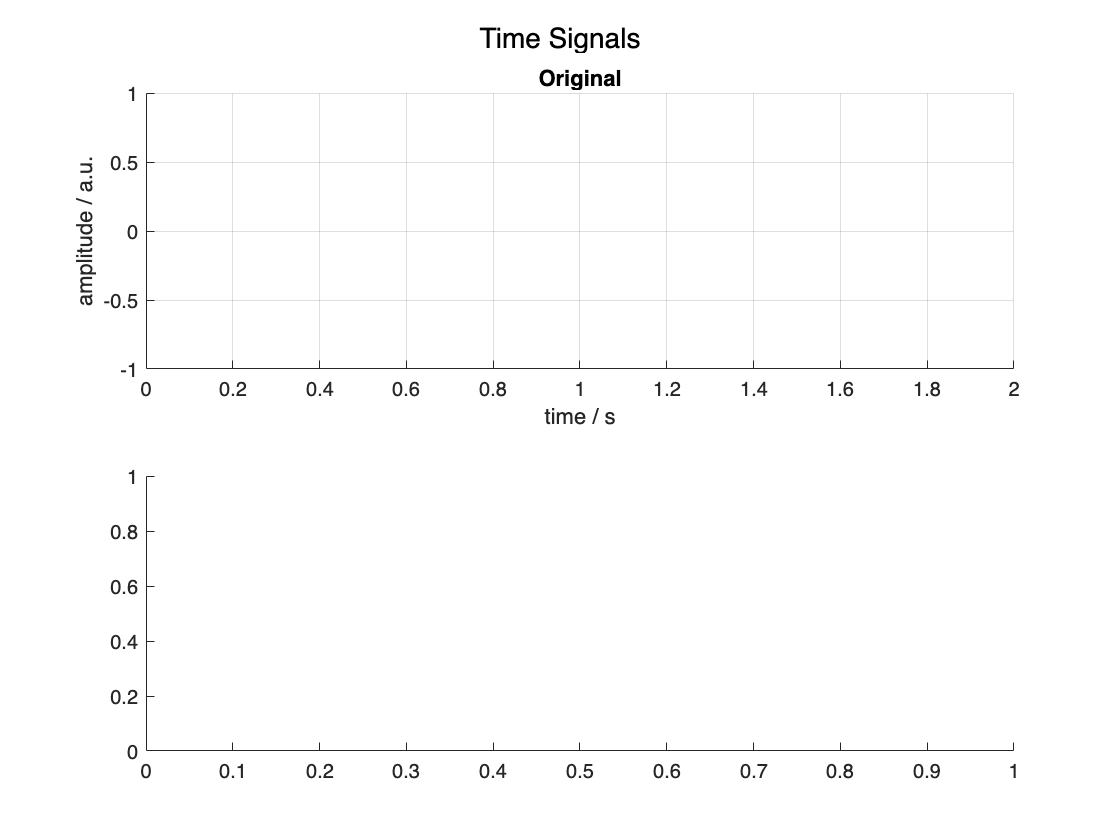

figure()
sgtitle('Time Signals','FontSize', 14) % Subplot title

subplot(2,1,1)
%plot(t,signal,'linewidth',1);
plot_specs(x_lim, y_lim, 'time / s', 'amplitude / a.u.', "Original","noleg")

subplot(2,1,2)

%plot(t,filtered_data_signal,'linewidth',1);
%plot_specs(x_lim, y_lim, 'time / s', 'amplitude / a.u.', "Filtered","noleg")

% Saving the plot
%save_plot('Results/filtered_and_original_signal');

**2) Magnitude/phase of Original Signal**

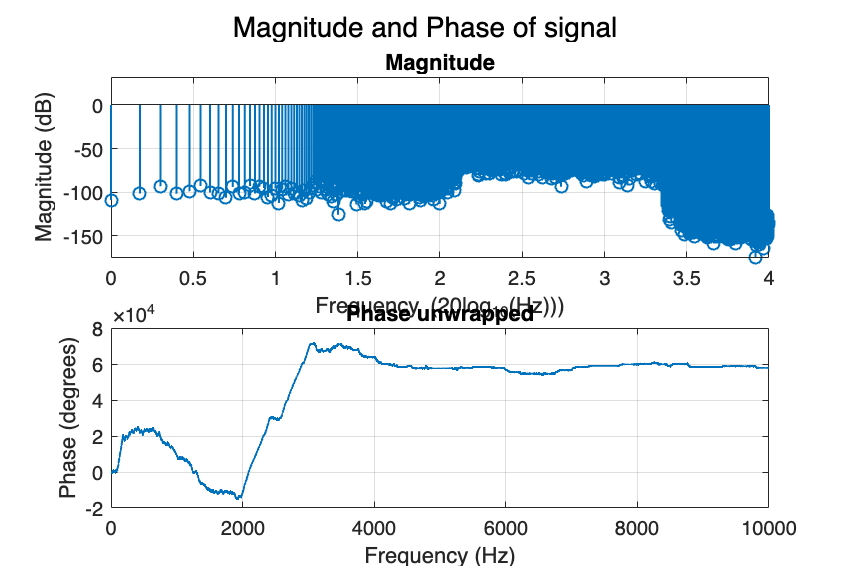

Figure saved as Results/magnitude_phase.pdf


figure
sgtitle( 'Magnitude and Phase of signal' ,'FontSize', 14)
% Only positive frequencies
fposit=f(f>=0); % length(f)/2 +1 (DC offset)
Yposit=Y(f>=0);
magnitude=abs(Yposit);
phase=angle(Yposit);

% Magnitude diagram ------------------------
% Specifications

% Correct string comparison for 'nyquist'
if strcmpi(x_lim_freq, 'nyquist') % Case-insensitive comparison
    x_lim_freq = fs / 2; % If 'nyquist', then set x_lim_freq to fs/2
else
    x_lim_freq_num = str2double(x_lim_freq);
    if isnan(x_lim_freq_num)
        error('Invalid value for x_lim_freq. It must be a numeric value or ''nyquist''.');
    else
        x_lim_freq = x_lim_freq_num;
    end
end

subplot(2, 1, 1);
ax = gca;
if y_axis_type == 'lin' % Frequency as a.u.
    if x_axis_type == 'lin' 
        stem(fposit, magnitude,'linewidth',1);
        ax.XLim = [0 x_lim_freq];
        xlabel('Frequency(Hz)');
    else
        % not using semilogx because preferred to used stem.
        stem(log10(fposit), magnitude,'linewidth',1)
        ax.XLim = [0 log10(x_lim_freq)];
        xlabel('Frequency (log_{10}(Hz)))');
    end
    ylabel('Magnitude (a.u.)')
    ax.YLim = [0 y_lim_au];
else % Frequency as decibels.
    if x_axis_type == 'lin' 
        stem(fposit, 20*log10(magnitude),'linewidth',1);
        ax.XLim = [0 x_lim_freq];
        xlabel('Frequency(Hz)');
    else
        stem(log10(fposit), 20*log10(magnitude),'linewidth',1); % not using semilogx, preferred to used stem.
        ax.XLim = [0 log10(x_lim_freq)];
        xlabel('Frequency (20log_{10}(Hz)))');
    end
    ylabel('Magnitude (dB)')
    ax.YLim = [min([20*log10(y_lim_au);20*log10(magnitude);0]), max([20*log10(y_lim_au);0;20*log10(magnitude)]) ];
end
set(ax,'FontSize',10)
grid()
title('Magnitude')


% Phase diagram ------------------------
subplot(2, 1, 2);
ax=gca;
plot(fposit, unwrap(phase)*180/pi,'linewidth',1);
title('Phase unwrapped');
ax.XLim = [0 x_lim_freq];
set(ax,'Fontsize',10) 
xlabel('Frequency (Hz)');
ylabel('Phase (degrees)');
grid()
set(gca,'Fontsize',10) % xtick could be added in specs and set here.
save_plot('Results/magnitude_phase');

**3) Real/Imaginary parts of Original Signal**

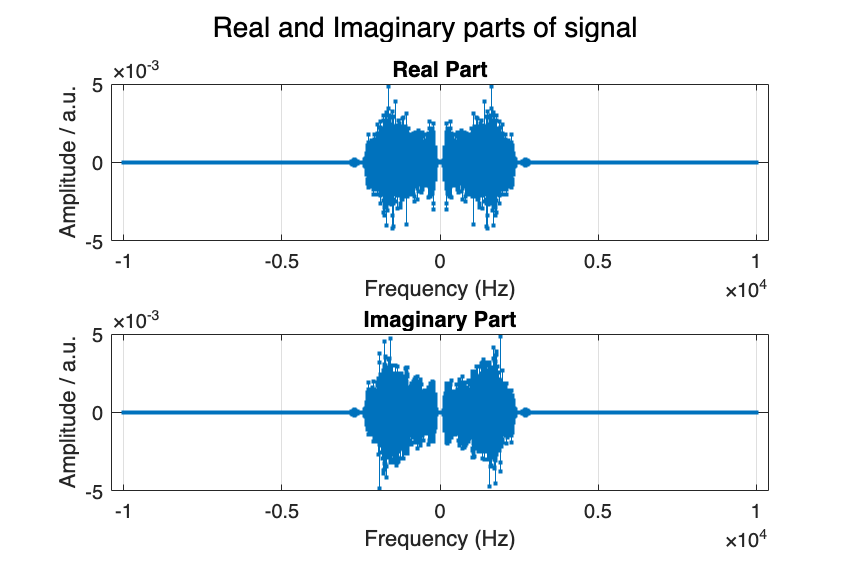

Figure saved as Results/real_imaginary.pdf


figure()
sgtitle('Real and Imaginary parts of signal','FontSize', 14)
% Plot the real and imaginary parts of the original and filtered signals
subplot(2, 1, 1);
stem(f,real(Y),'.');
xlabel('Frequency (Hz)')
%ylim([-y_lim_au,y_lim_au])
ylabel('Amplitude / a.u.')
title("Real Part")
grid()
set(gca,'Fontsize',10) % xticks could be added
subplot(2, 1, 2);
stem(f,imag(Y),'.');
xlabel('Frequency (Hz)')
%ylim([-y_lim_au,y_lim_au])
ylabel('Amplitude / a.u.')
title("Imaginary Part")
grid()

% Save to plot
save_plot('Results/real_imaginary');

**4) Pole/zero diagram**

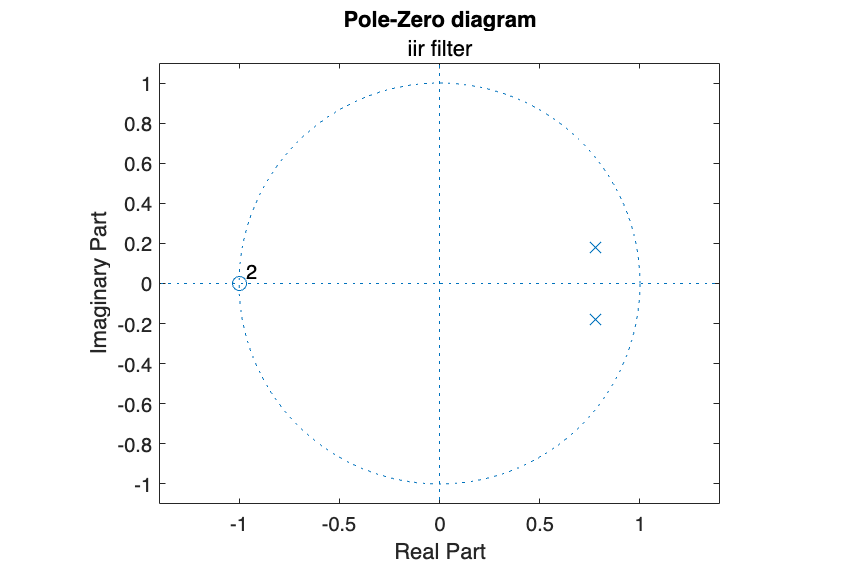

Figure saved as Results/pole_zero.pdf


Fpoles = roots(a);
Fzeros = roots(b);

figure()
zplane(Fzeros, Fpoles);
title('Pole-Zero diagram');
subtitle([structure.filtering ' filter']);
save_plot('Results/pole_zero');

**5) Filter transfer function  **

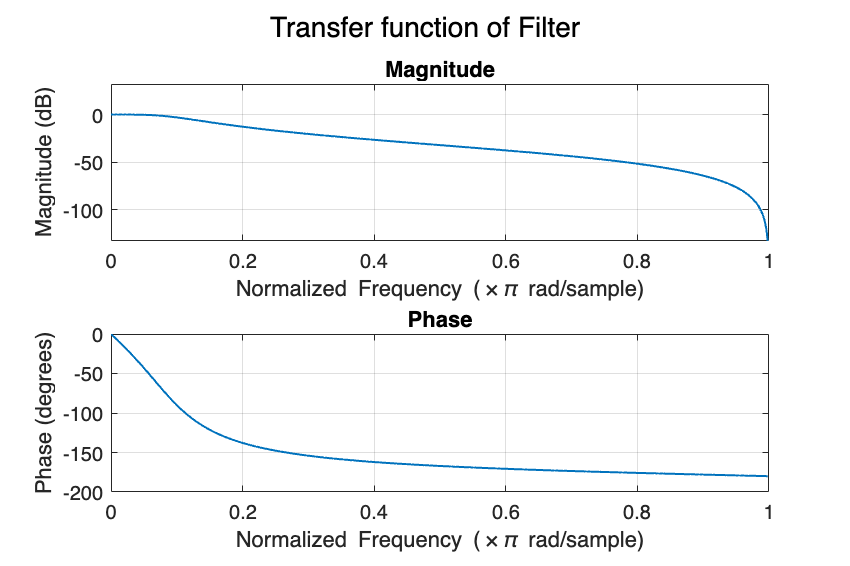

Figure saved as Results/transfer_function.pdf


[h,w] = freqz(b,a);
figure()
sgtitle('Transfer function of Filter','FontSize', 14)
subplot(2,1,1)
ax = gca;

% Magnitude response in decibels.

if y_axis_type == 'lin' % Frequency as a.u.
    plot(w/pi,abs(h),'linewidth',1) % normalized frequency, freq response in dB scale
    ylabel('Magnitude (a.u.)')
    ax.YLim = [0 y_lim_au];
else % Frequency as decibels.
    plot(w/pi, 20*log10(abs(h)),'linewidth',1); % not using semilogx, preferred to used stem.
    xlabel('Frequency (20log_{10}(Hz)))');
    ylabel('Magnitude (dB)')
    ax.YLim = [min([20*log10(y_lim_au);20*log10(abs(h));0]), max([20*log10(y_lim_au);20*log10(abs(h));0])];
end
ax.XTick = 0:.2:1; % could delete
ax.XLim = [0 1]; % normalized freq
xlabel('Normalized Frequency (\times\pi rad/sample)');
set(ax,'FontSize',10)
grid()
title('Magnitude')

% Phase diagram ------------------------
subplot(2,1,2) % Automatic axis here
ax=gca;
plot(w/pi, unwrap(angle(h))*180/pi,'linewidth',1);
xlabel('Normalized Frequency (\times\pi rad/sample)')
ylabel('Phase (degrees)')
set(ax,'Fontsize',10)
grid()
title("Phase")
save_plot('Results/transfer_function');% Ensure the original signal, filtered signal, and sampling frequency are defined

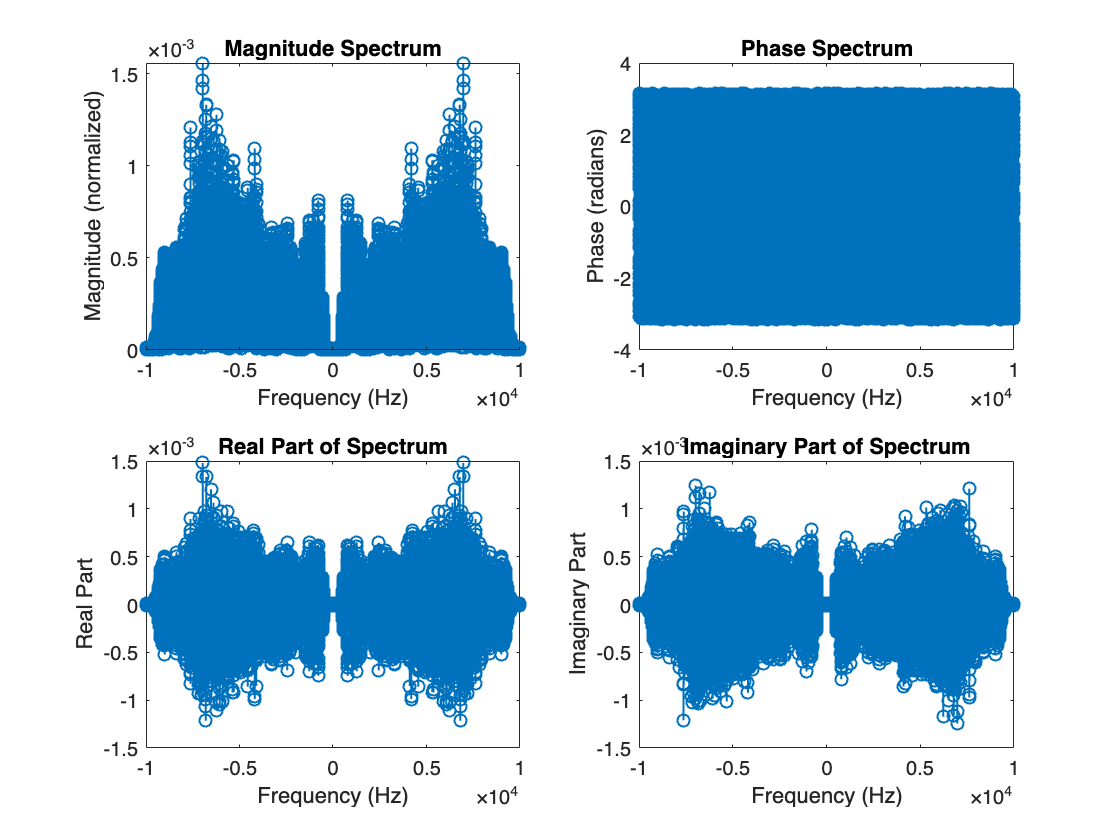

% Variables:
%   signal               - Original signal vector
%   filtered_data_signal - Filtered signal vector
%   fs                   - Sampling frequency
%   spectral_resolution  - Desired spectral resolution for the spectrum

% Compute the magnitude spectrum of the original signal
[Original_Y, freq] = make_spectrum(signal, fs, spectral_resolution);

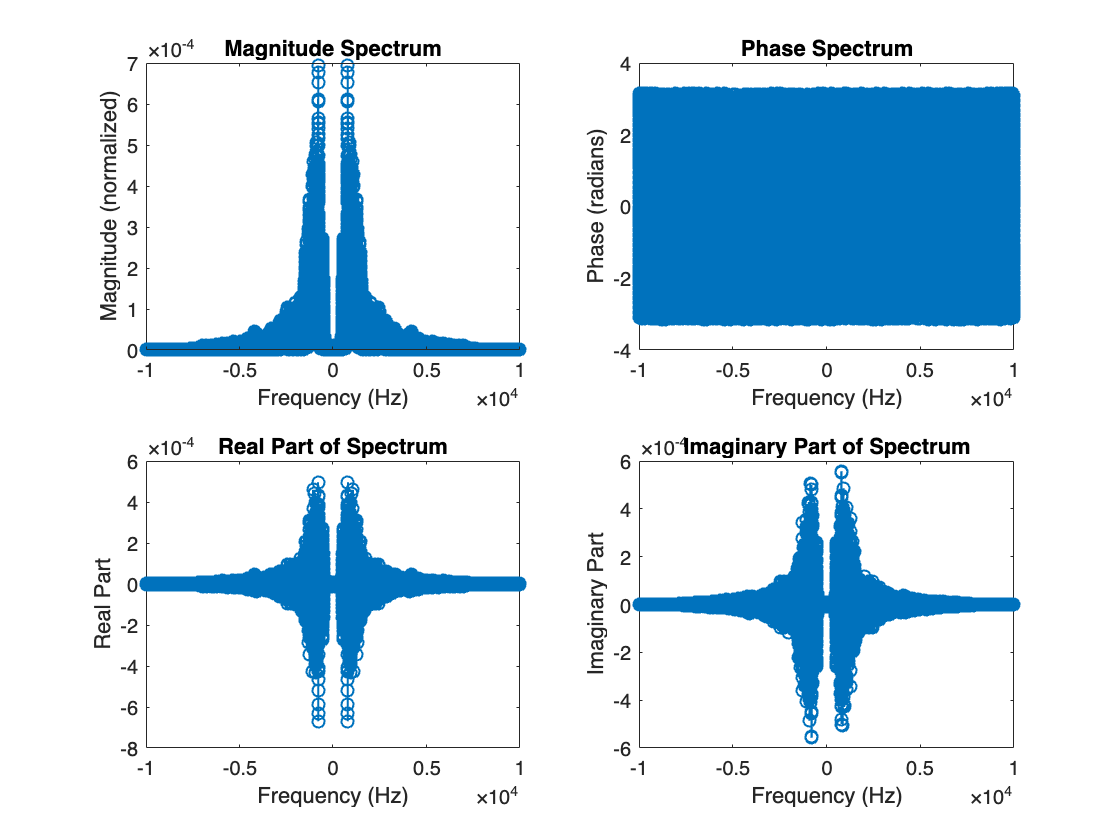

Original_magnitude = abs(Original_Y);

% Compute the magnitude spectrum of the filtered signal
[Filtered_Y, ~] = make_spectrum(filtered_data_signal, fs, spectral_resolution);

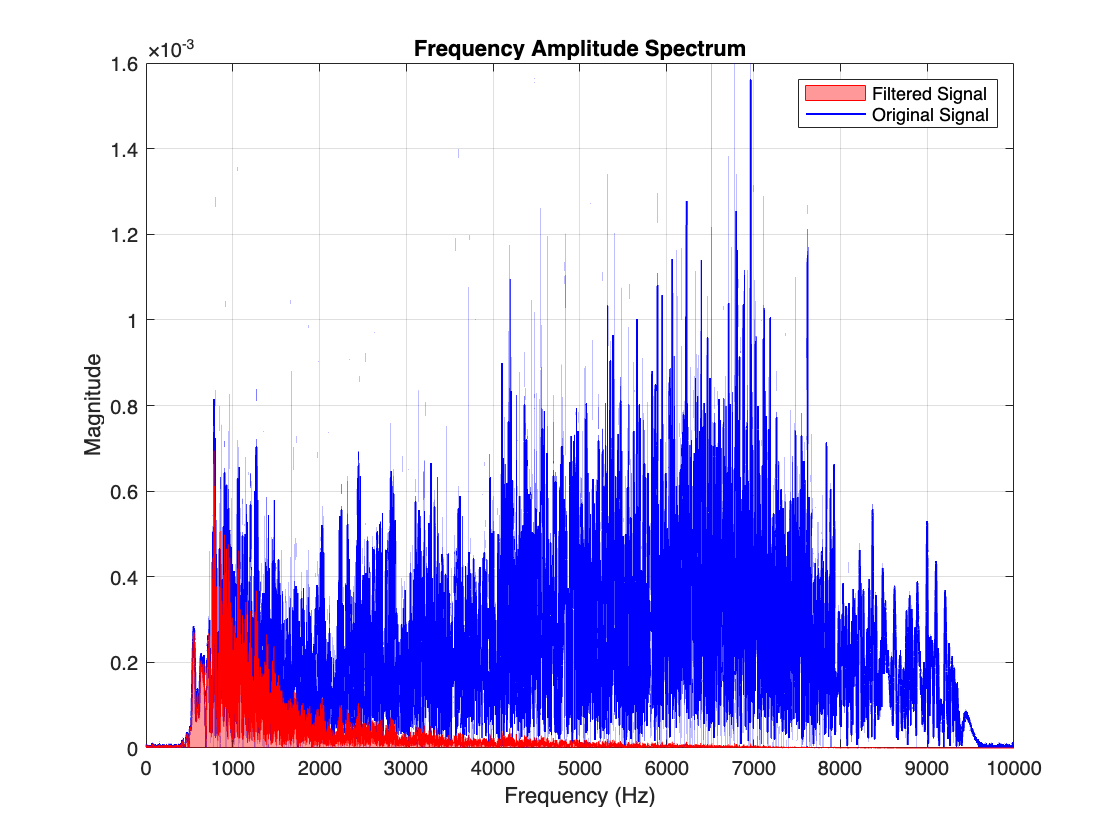

Filtered_magnitude = abs(Filtered_Y);

% Plot the magnitude spectra of both signals on the same plot
figure;

% Plot the original signal spectrum using 'plot'
plot(freq, Original_magnitude, 'b', 'LineWidth', 1); % Original signal in blue
hold on;

% Plot the filtered signal spectrum using 'area' with transparency
% Create a filled area under the filtered signal's magnitude spectrum
h_area = area(freq, Filtered_magnitude);
set(h_area, 'FaceColor', 'r', 'EdgeColor', 'r', 'FaceAlpha', 0.4);

% Set plot properties
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Frequency Amplitude Spectrum');
legend('Original Signal', 'Filtered Signal');
grid on;
xlim([0 fs/2]); % Limit x-axis to positive frequencies up to Nyquist frequency

hold off;